clear all
clc

## Funwork 4

Phillipp Gery

syms theta1 theta2 x_pos theta1_dot theta2_dot x_dot

syms theta1_ddot theta2_ddot x_ddot
syms u1 u2 u3 x

%get Results from Funwork1 means Model 
load("../Funwork3/Funwork3_Gery_Results.mat");
disp("non-linear model")

non-linear model


disp(f_u3)

$$\begin{array}{l} \left(\begin{array}{c} \dot{x}\\ \theta_{\dot{1}}\\ \theta_{\dot{2}}\\ -\frac{840\,u_{1}-2943\,\sin\left(2\,\theta_{1}\right)+300\,{\theta_{\dot{1}}}^{2}\,\sin\left(\theta_{1}\right)+135\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{2}\right)-360\,u_{1}\,\cos\left(\sigma_{5}\right)+800\,u_{3}\,\sigma_{2}-1680\,u_{2}\,\cos\left(\theta_{1}\right)-800\,u_{3}\,\cos\left(\theta_{2}\right)+135\,{\theta_{\dot{2}}}^{2}\,\sigma_{1}+720\,u_{2}\,\sigma_{3}}{60\,\sigma_{4}}\\ \frac{3600\,u_{2}\,\cos\left(2\,\theta_{2}\right)-26487\,\sin\left(\theta_{1}-2\,\theta_{2}\right)-91233\,\sin\left(\theta_{1}\right)-22800\,u_{2}+4725\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)+750\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{1}\right)-4000\,u_{3}\,\cos\left(\theta_{1}+\theta_{2}\right)+4200\,u_{1}\,\cos\left(\theta_{1}\right)+1350\,{\theta_{\dot{1}}}^{2}\,\sin\left(\sigma_{5}\right)-1800\,u_{1}\,\sigma_{3}+13600\,u_{3}\,\cos\left(\theta_{1}-\theta_{2}\right)+675\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{150\,\sigma_{4}}\\ -\frac{2700\,\sin\left(\theta_{1}-\theta_{2}\right)\,{\theta_{\dot{1}}}^{2}+1215\,\sin\left(\sigma_{5}\right)\,{\theta_{\dot{2}}}^{2}+13600\,u_{3}-26487\,\sigma_{1}+26487\,\sin\left(\theta_{2}\right)-4000\,u_{3}\,\cos\left(2\,\theta_{1}\right)+1800\,u_{1}\,\sigma_{2}+3600\,u_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-1800\,u_{1}\,\cos\left(\theta_{2}\right)-12240\,u_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{135\,\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\theta_{1}-\theta_{2}\right)\\ \sigma_{2}=\cos\left(2\,\theta_{1}-\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{1}-2\,\theta_{2}\right)\\ \sigma_{4}=5\,\cos\left(2\,\theta_{1}\right)+9\,\cos\left(\sigma_{5}\right)-26\\ \sigma_{5}=2\,\theta_{1}-2\,\theta_{2} \end{array}$$

## Problem 1.

(4 pts) Discretize the linearized model about the equilibrium pair from FunWork 3 and use it as the design model. You as a designer select the sampling period .

h = 0.01;

sys_c = ss(A_u3, B_u3, C_u3, D_u3);

% continuous-to-discrete conversion using Zero-Order Hold (ZOH)
sys_d = c2d(sys_c, h, 'zoh');


Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C; 
Dd = sys_d.D;

% C and D stay the same



Discretized System Matrix Ad:

disp(Ad);

    1.0000   -0.0000   -0.0001    0.0100   -0.0000   -0.0000
         0    1.0011   -0.0009         0    0.0100   -0.0000
         0   -0.0007    1.0011         0   -0.0000    0.0100
         0   -0.0053   -0.0113    1.0000   -0.0000   -0.0001
         0    0.2252   -0.1782         0    1.0011   -0.0009
         0   -0.1400    0.2179         0   -0.0007    1.0011



Discretized Input Matrix Bd:

disp(Bd);

    0.0000   -0.0000   -0.0000
   -0.0000    0.0004   -0.0002
   -0.0000   -0.0002    0.0003
    0.0043   -0.0017   -0.0029
   -0.0017    0.0735   -0.0457
   -0.0029   -0.0457    0.0558



Sampling Period (Ts):

disp(h);

    0.0100



## Problem 2.

 (7 pts) First design an MPC using the augmented model without any constraints and implement the controller on the nonlinear continuous model. Write a script that animates the behavior of the closed-loop system.

### The Augmented Model:

%MPC horizons
p = 100; 
m = 10;  

% Create the MPC object
mpc_obj = mpc(sys_d, h, p, m);

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.



% Weights: [x, theta1, theta2]
mpc_obj.Weights.OutputVariables = [2, 20, 20];
% Weights: [u1, u2, u3]
mpc_obj.Weights.ManipulatedVariables = [0.1, 0.1, 0.1];
% no constrains
mpc_obj.MV = struct('Min', -Inf, 'Max', +Inf);

-->The number of elements in the "ManipulatedVariables" property is smaller than 3. Assuming default values.


mpc_obj.OV = struct('Min', -Inf, 'Max', +Inf);

-->The number of elements in the "OutputVariables" property is smaller than 3. Assuming default values.


%equilibrium!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
mpc_obj.Model.Nominal.X = xe_vals;
mpc_obj.Model.Nominal.U = ue;      
mpc_obj.Model.Nominal.Y = C_u3 * xe_vals;

x_init = [0.2; 0.2; 0.2; 0; 0; 0];
sim_time = 5;
r_target = C_u3 * xe_vals;

f_handle_3u = matlabFunction(f_u3, 'Vars', {state_vector, input_vector});
[T1, X1, U1] = run_mpc_simulation(mpc_obj, f_handle_3u, C_u3, x_init, h, sim_time, r_target, xe_vals, ue, 'mpc_sim_P2.mp4');

Starting non-linear simulation...
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
   Assuming no disturbance added to measured output #1.
-->"Model.Noise" is empty. Assuming white noise on each measured output.
Simulation complete. Starting animation...
Animation video file saved as: mpc_sim_P2.mp4


Simulation Results

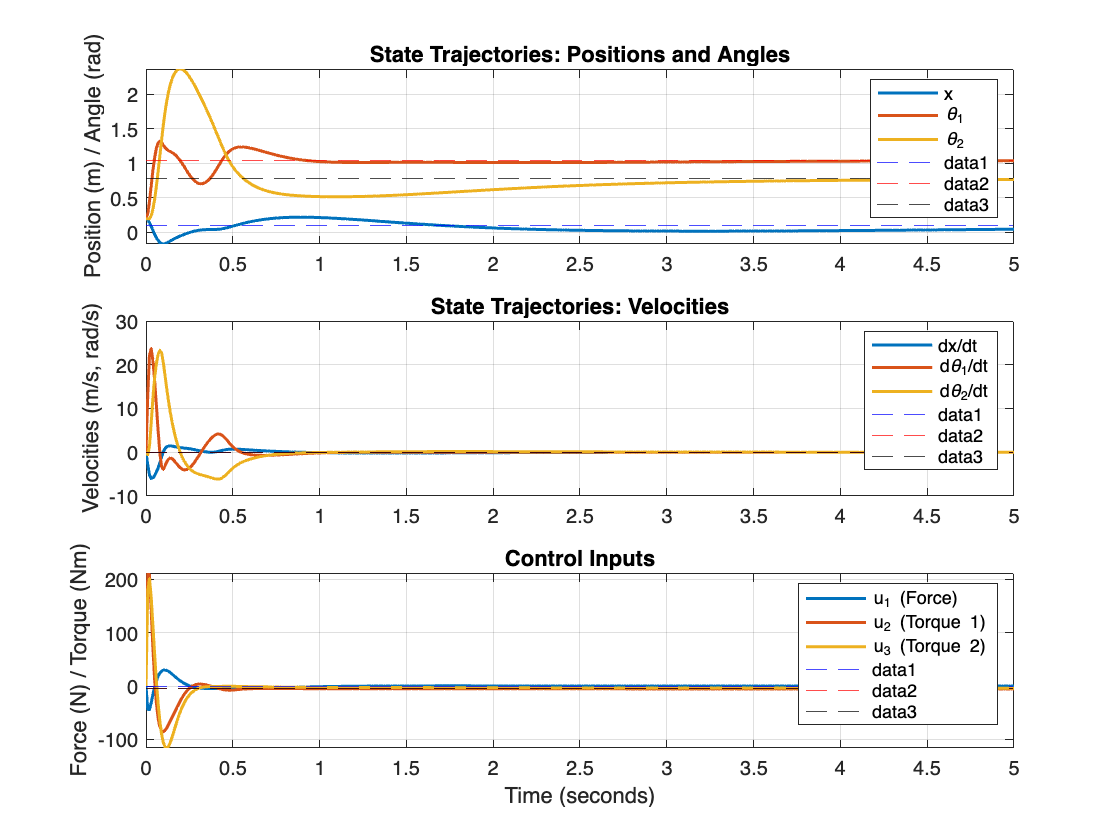

figure('Name', 'MPC Simulation Results without constrains');

subplot(3, 1, 1);
plot(T1, X1(:, 1:3), 'LineWidth', 1.5);
title('State Trajectories: Positions and Angles');
ylabel('Position (m) / Angle (rad)');
legend('x', '\theta_1', '\theta_2', 'Location', 'northeast');
yline(xe_vals(1), 'b--');
yline(xe_vals(2), 'r--');
yline(xe_vals(3), 'k--');
grid on;

subplot(3, 1, 2);
plot(T1, X1(:, 4:6), 'LineWidth', 1.5);
title('State Trajectories: Velocities');
ylabel('Velocities (m/s, rad/s)');
legend('dx/dt', 'd\theta_1/dt', 'd\theta_2/dt', 'Location', 'northeast');
yline(xe_vals(4), 'b--');
yline(xe_vals(5), 'r--');
yline(xe_vals(6), 'k--');
grid on;

subplot(3, 1, 3);
plot(T1, U1, 'LineWidth', 1.5);
title('Control Inputs');
ylabel('Force (N) / Torque (Nm)');
xlabel('Time (seconds)');
legend('u_1 (Force)', 'u_2 (Torque 1)', 'u_3 (Torque 2)', 'Location', 'northeast');
yline(ue(1), 'b--');
yline(ue(2), 'r--');
yline(ue(3), 'k--');
grid on;

## **Problem 3.**

** (7 pts)** Impose constraints on the inputs and outputs. Re-design your MPC. Implement the controller on the nonlinear continuous model. Write a script that animates the behavior of the closed-loop system.

%Add constrains to model
mpc_obj.MV(1).Min = -70; mpc_obj.MV(1).Max = 70;  
mpc_obj.MV(2).Min = -40; mpc_obj.MV(2).Max = 40;  
mpc_obj.MV(3).Min = -40; mpc_obj.MV(3).Max = 40;


mpc_obj.OV(1).Min = -2; mpc_obj.OV(1).Max = 2;   
mpc_obj.OV(2).Min = -2; mpc_obj.OV(2).Max = 2; 
mpc_obj.OV(3).Min = -2; mpc_obj.OV(3).Max = 2;

f_handle_3u = matlabFunction(f_u3, 'Vars', {state_vector, input_vector});
[T1, X1, U1] = run_mpc_simulation(mpc_obj, f_handle_3u, C_u3, x_init, h, sim_time, r_target, xe_vals, ue, 'mpc_sim_P3.mp4');

Starting non-linear simulation...
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
   Assuming no disturbance added to measured output #1.
-->"Model.Noise" is empty. Assuming white noise on each measured output.
Simulation complete. Starting animation...
Animation video file saved as: mpc_sim_P3.mp4


Simulation Results

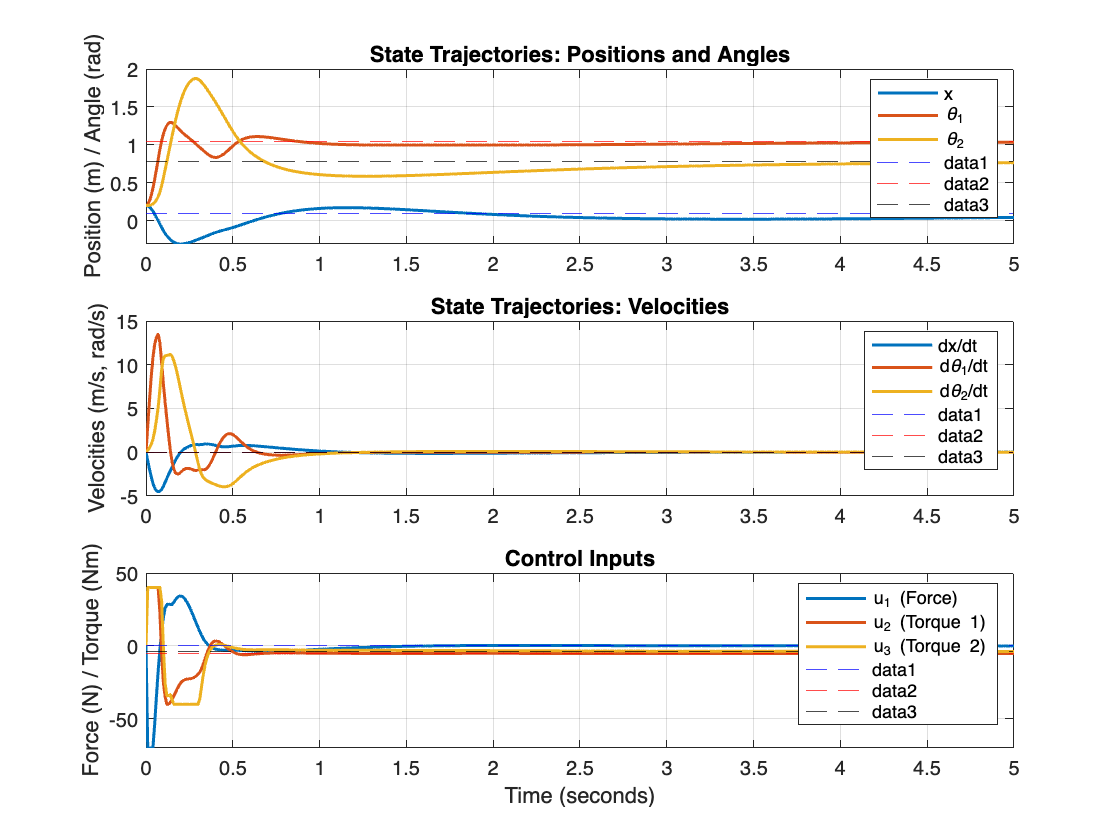

figure('Name', 'MPC Simulation Results with constrains');

subplot(3, 1, 1);
plot(T1, X1(:, 1:3), 'LineWidth', 1.5);
title('State Trajectories: Positions and Angles');
ylabel('Position (m) / Angle (rad)');
legend('x', '\theta_1', '\theta_2', 'Location', 'northeast');
yline(xe_vals(1), 'b--');
yline(xe_vals(2), 'r--');
yline(xe_vals(3), 'k--');
grid on;

subplot(3, 1, 2);
plot(T1, X1(:, 4:6), 'LineWidth', 1.5);
title('State Trajectories: Velocities');
ylabel('Velocities (m/s, rad/s)');
legend('dx/dt', 'd\theta_1/dt', 'd\theta_2/dt', 'Location', 'northeast');
yline(xe_vals(4), 'b--');
yline(xe_vals(5), 'r--');

yline(xe_vals(6), 'k--');
grid on;

subplot(3, 1, 3);
plot(T1, U1, 'LineWidth', 1.5);
title('Control Inputs');
ylabel('Force (N) / Torque (Nm)');
xlabel('Time (seconds)');
legend('u_1 (Force)', 'u_2 (Torque 1)', 'u_3 (Torque 2)', 'Location', 'northeast');
yline(ue(1), 'b--');
yline(ue(2), 'r--');
yline(ue(3), 'k--');
grid on;

## **Problem 4.**

** (7 pts)** Implement the combined MPC controller-observer compensator and test it on the nonlinear continuous-time (CT) model. Write a script that animates the behavior of the closed-loop system.

%using Oberserver from Funwork3

poles_obs_d = exp(eig(A_u3 - L*C_u3) * h); % Map continuous poles to discrete poles
Ld = place(Ad', C_u3', poles_obs_d)';

disp(Ld)

    0.2453   -0.1049   -0.0153
    0.0879    0.2695   -0.0991
   -0.0284    0.1119    0.2417
    1.6081   -1.1410   -0.3221
    1.0032    2.2648   -1.3279
   -0.4275    1.0954    1.7555



eig(Ad-Ld*Cd)

ans =    0.8495 + 0.1573i
   0.8495 - 0.1573i
   0.9049 + 0.0000i
   0.8744 + 0.0000i
   0.8848 + 0.0151i
   0.8848 - 0.0151i


%using internal Observer --> Kalman filter
[T_obs, X_obs, U_obs, X_hat_obs] = run_mpc_sim_with_Observer(mpc_obj,f_handle_3u, Ad, Bd, Cd, C_u3, x_init , Ld, h, sim_time, r_target, xe_vals, ue, 'mpc_sim_P4.mp4');

Starting DISCRETE plant simulation with MPC...
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
   Assuming no disturbance added to measured output #1.
-->"Model.Noise" is empty. Assuming white noise on each measured output.
Simulation complete. Starting animation...
Animation video file saved as: mpc_sim_P4.mp4


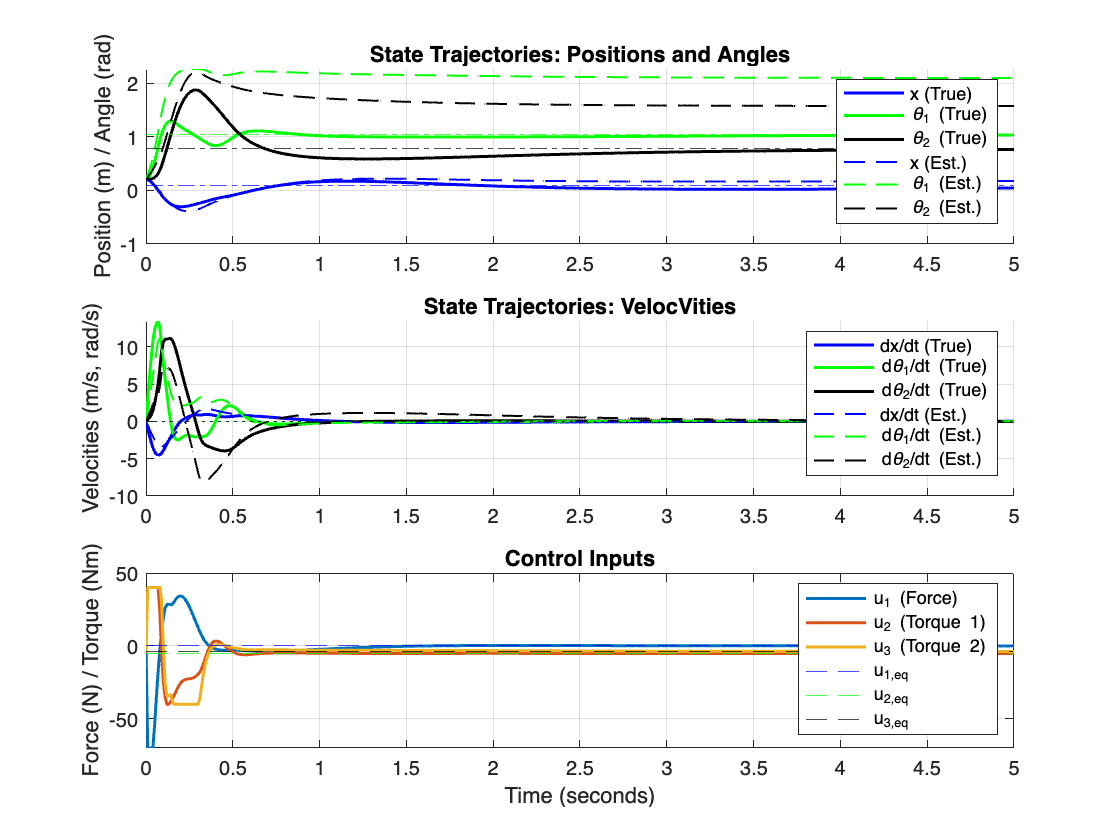


%External addtional Observer
%[T_obs, X_obs, U_obs, X_hat_obs] = run_mpc_with_Ld_observer(mpc_obj, f_handle_3u, Ad, Bd, Cd, Ld, C_u3, x_init, h, sim_time, r_target, xe_vals, ue, 'mpc_sim_P4.mp4')

figure('Name', 'MPC Discrete Simulation: True vs. Estimated States');

% Plot 1: Positions and Angles
subplot(3, 1, 1);
hold on;
% Plot True States (solid lines)
plot(T_obs, X_obs(:, 1), 'b-', 'LineWidth', 1.5);
plot(T_obs, X_obs(:, 2), 'g-', 'LineWidth', 1.5);
plot(T_obs, X_obs(:, 3), 'k-', 'LineWidth', 1.5);
% Plot Estimated States (dashed lines)
plot(T_obs, X_hat_obs(:, 1), 'b--', 'LineWidth', 1);
plot(T_obs, X_hat_obs(:, 2), 'g--', 'LineWidth', 1);
plot(T_obs, X_hat_obs(:, 3), 'k--', 'LineWidth', 1);
% Add equilibrium lines
yline(xe_vals(1), 'b-.');
yline(xe_vals(2), 'g-.');
yline(xe_vals(3), 'k-.');
hold off;
title('State Trajectories: Positions and Angles');
ylabel('Position (m) / Angle (rad)');
legend('x (True)', '\theta_1 (True)', '\theta_2 (True)', 'x (Est.)', '\theta_1 (Est.)', '\theta_2 (Est.)', 'Location', 'northeast');
grid on;

% Plot 2: Velocities
subplot(3, 1, 2);
hold on;
% Plot True States (solid lines)
plot(T_obs, X_obs(:, 4), 'b-', 'LineWidth', 1.5);
plot(T_obs, X_obs(:, 5), 'g-', 'LineWidth', 1.5);
plot(T_obs, X_obs(:, 6), 'k-', 'LineWidth', 1.5);
% Plot Estimated States (dashed lines)
plot(T_obs, X_hat_obs(:, 4), 'b--', 'LineWidth', 1);
plot(T_obs, X_hat_obs(:, 5), 'g--', 'LineWidth', 1);
plot(T_obs, X_hat_obs(:, 6), 'k--', 'LineWidth', 1);
% Add equilibrium lines
yline(xe_vals(4), 'b:');
yline(xe_vals(5), 'g:');
yline(xe_vals(6), 'k:');
hold off;
title('State Trajectories: VelocVities');
ylabel('Velocities (m/s, rad/s)');
legend('dx/dt (True)', 'd\theta_1/dt (True)', 'd\theta_2/dt (True)', 'dx/dt (Est.)', 'd\theta_1/dt (Est.)', 'd\theta_2/dt (Est.)', 'Location', 'northeast');
grid on;

% Plot 3: Control Inputs
subplot(3, 1, 3);
plot(T_obs, U_obs, 'LineWidth', 1.5);
hold on;
% Add equilibrium input lines
yline(ue(1), 'b--');
yline(ue(2), 'g--');
yline(ue(3), 'k--');
hold off;
title('Control Inputs');
ylabel('Force (N) / Torque (Nm)');
xlabel('Time (seconds)');
legend('u_1 (Force)', 'u_2 (Torque 1)', 'u_3 (Torque 2)', 'u_{1,eq}', 'u_{2,eq}', 'u_{3,eq}', 'Location', 'northeast');
grid on;

## **Problem 4, Part 2.**

** (3 pts) **Produce a video of your animation and submit your video to the [FunWork 4 - Problem 4, Part 2](https://purdue.brightspace.com/d2l/common/dialogs/quickLink/quickLink.d2l?ou=1361064&type=dropbox&rcode=354644E0-4CD8-419D-A32F-4E78D8778E5C-6948521) assignment link. (NOTE: This is the only part of your assignment that you do *not* need to submit to Gradescope.

Output for 3D Simulation in Simulink



%  physical parameters
l1 = 0.5; 
l2 = 0.75; 
g = 9.81;

% Cart dimensions 
cart_width = 0.5;
cart_height = 0.25;

% the i use it with Fromworkspace blocks
x_res = timeseries(X_obs(:,1), T_obs);
Theta1_res = timeseries(X_obs(:,2), T_obs);
Theta2_res = timeseries(X_obs(:,3), T_obs);

## **Problem 5.**

** (12 pts)** Repeat your MPC designs using the non-augmented model.

WITHOUT MATLAB TOOLBOX

started from sratch with Lecture notes becasue no differnce with matlab toolbox between Aug and NON Aug Model


n = size(Ad, 1); % n = 6
m = size(Bd, 2); % m = 3
p = size(Cd, 1); % p = 3



p_horizon = 100; % Prediction horizon (Np)

% Define cost matrices Q and R
Q0 = diag([2, 20, 20]); 
R0 = 0.1 * eye(m);       

% Create the large block-diagonal Q and R matrices for the horizon
Q_mpc = kron(eye(p_horizon), Q0);
R_mpc = kron(eye(p_horizon), R0);

% --- Calculate the W and Z matrices (Eq. 9, Page 3) ---
W = zeros(p_horizon * p, n);
Z = zeros(p_horizon * p, p_horizon * m);
temp_Z = zeros(p, p_horizon * m);

for i = 1:p_horizon
    % W = [C*A; C*A^2; ... C*A^p]
    W( (i-1)*p + 1 : i*p , : ) = Cd * (Ad^i);
    
    % Z = [CB, 0, ...; CAB, CB, ...; CA^pB, ..., CB]
    temp_Z = [Cd*(Ad^(i-1))*Bd, temp_Z(:, 1:end-m)];
    Z( (i-1)*p + 1 : i*p , : ) = temp_Z;
end


% K_inv = (R + Z'*Q*Z)^-1
K_inv = (R_mpc + Z' * Q_mpc * Z) \ eye(size(R_mpc));
% Kr = [I 0...0] * (R+Z'QZ)^-1 * Z'*Q
K_r = [eye(m), zeros(m, (p_horizon-1)*m)] * K_inv * Z' * Q_mpc

K_r =     0.0004   -0.0017   -0.0026    0.0012   -0.0049   -0.0076    0.0021   -0.0080   -0.0121    0.0028   -0.0109   -0.0161    0.0036   -0.0136   -0.0197    0.0044   -0.0161   -0.0229    0.0051   -0.0185   -0.0257    0.0059   -0.0206   -0.0282    0.0066   -0.0226   -0.0304    0.0073   -0.0244   -0.0324    0.0080   -0.0260   -0.0340    0.0087   -0.0274   -0.0354    0.0094   -0.0287   -0.0366    0.0101   -0.0298   -0.0376    0.0108   -0.0307   -0.0384    0.0114   -0.0315   -0.0391    0.0121   -0.0321
   -0.0002    0.0610   -0.0365   -0.0005    0.1719   -0.1015   -0.0008    0.2619   -0.1514   -0.0010    0.3336   -0.1882   -0.0013    0.3892   -0.2137   -0.0015    0.4308   -0.2296   -0.0017    0.4604   -0.2372   -0.0019    0.4797   -0.2381   -0.0020    0.4903   -0.2333   -0.0021    0.4936   -0.2241   -0.0022    0.4909   -0.2112   -0.0023    0.4832   -0.1956   -0.0024    0.4716   -0.1781   -0.0024    0.4569   -0.1592   -0.0025    0.4399   -0.1395   -0.0025    0.4212   -0.1194   -0.0025   

% Kx = Kr * W
K_x = K_r * W

K_x =     2.9967   -1.4979   -1.9783    1.9608   -0.2274   -0.2766
    0.2028   16.3890    0.0537    0.1991    2.7273    1.2454
    0.2753    0.4469   17.4495    0.2667    1.3097    3.3155


USE the Discrete-Time Observer

disp(Ld)

    0.2453   -0.1049   -0.0153
    0.0879    0.2695   -0.0991
   -0.0284    0.1119    0.2417
    1.6081   -1.1410   -0.3221
    1.0032    2.2648   -1.3279
   -0.4275    1.0954    1.7555



%Simulation 
[T_obs_NA, X_obs_NA, X_hat_obs_NA, U_obs_NA] = run_manual_mpc_sim(f_handle_3u, Ad, Bd, Cd, K_x, K_r, Ld, x_init, h, sim_time, r_target, xe_vals, ue, 'manual_mpc_sim_NONAUG.mp4');

Starting manual MPC + Observer simulation...
Simulation complete. Starting animation...
Animation video file saved as: manual_mpc_sim_NONAUG.mp4


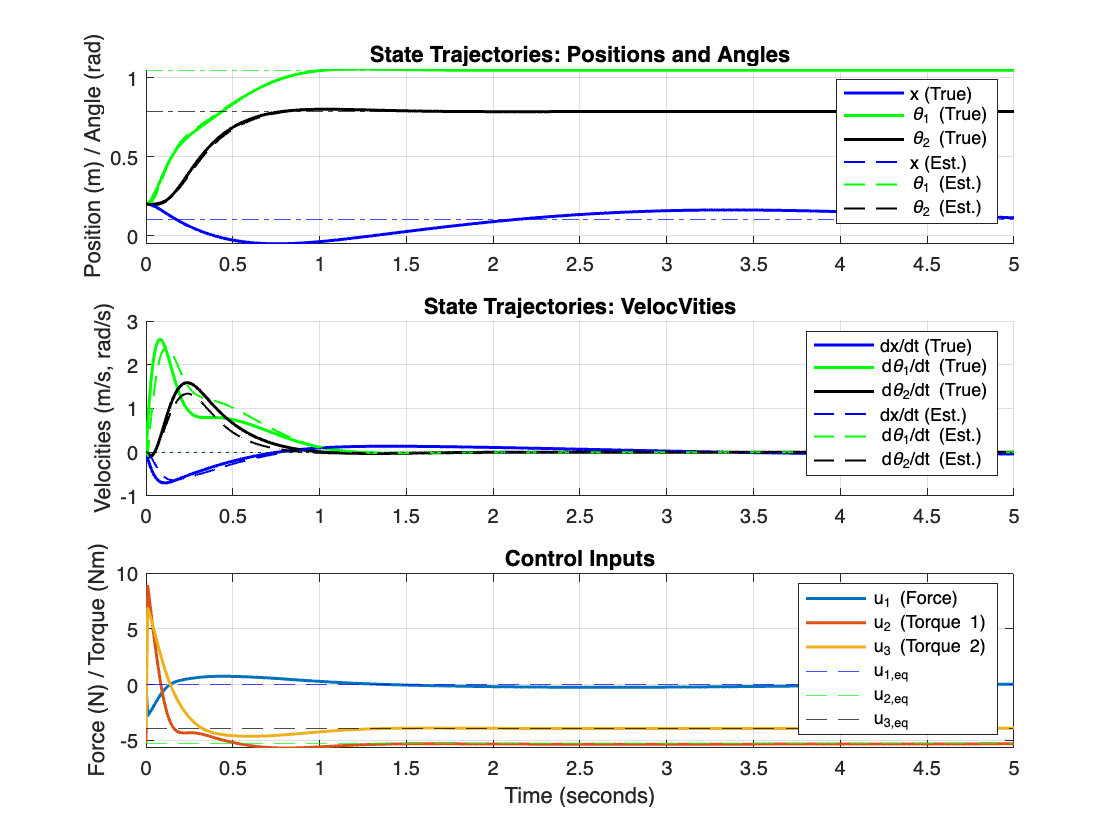


figure('Name', 'NonAugmMPC Simulation: True vs. Estimated States');

% Plot 1: Positions and Angles
subplot(3, 1, 1);
hold on;
% Plot True States (solid lines)
plot(T_obs_NA, X_obs_NA(:, 1), 'b-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 2), 'g-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 3), 'k-', 'LineWidth', 1.5);
% Plot Estimated States (dashed lines)
plot(T_obs_NA, X_hat_obs_NA(:, 1), 'b--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 2), 'g--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 3), 'k--', 'LineWidth', 1);
% Add equilibrium lines
yline(xe_vals(1), 'b-.');
yline(xe_vals(2), 'g-.');
yline(xe_vals(3), 'k-.');
hold off;
title('State Trajectories: Positions and Angles');
ylabel('Position (m) / Angle (rad)');
legend('x (True)', '\theta_1 (True)', '\theta_2 (True)', 'x (Est.)', '\theta_1 (Est.)', '\theta_2 (Est.)', 'Location', 'northeast');
grid on;

% Plot 2: Velocities
subplot(3, 1, 2);
hold on;
% Plot True States (solid lines)
plot(T_obs_NA, X_obs_NA(:, 4), 'b-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 5), 'g-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 6), 'k-', 'LineWidth', 1.5);
% Plot Estimated States (dashed lines)
plot(T_obs_NA, X_hat_obs_NA(:, 4), 'b--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 5), 'g--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 6), 'k--', 'LineWidth', 1);
% Add equilibrium lines
yline(xe_vals(4), 'b:');
yline(xe_vals(5), 'g:');
yline(xe_vals(6), 'k:');
hold off;
title('State Trajectories: VelocVities');
ylabel('Velocities (m/s, rad/s)');
legend('dx/dt (True)', 'd\theta_1/dt (True)', 'd\theta_2/dt (True)', 'dx/dt (Est.)', 'd\theta_1/dt (Est.)', 'd\theta_2/dt (Est.)', 'Location', 'northeast');
grid on;

% Plot 3: Control Inputs
subplot(3, 1, 3);
plot(T_obs_NA, U_obs_NA, 'LineWidth', 1.5);
hold on;
% Add equilibrium input lines
yline(ue(1), 'b--');
yline(ue(2), 'g--');
yline(ue(3), 'k--');
hold off;
title('Control Inputs');
ylabel('Force (N) / Torque (Nm)');
xlabel('Time (seconds)');
legend('u_1 (Force)', 'u_2 (Torque 1)', 'u_3 (Torque 2)', 'u_{1,eq}', 'u_{2,eq}', 'u_{3,eq}', 'Location', 'northeast');
grid on;

save("Funwork4_Gery_Results", "A_u3", "B_u3", "C_u3", "D_u3", "Ad", "Bd", "Cd", "Dd", "L", "f_u3", "state_vector", "input_vector", "xe_vals", "ue")


return

### WITH MATLAB TOOLBOX


% integartor behaviour deaktivated
mpc_obj.Model.Disturbance = [];

[T_obs_NA, X_obs_NA, U_obs_NA, X_hat_obs_NA] = run_mpc_sim_with_Observer(mpc_obj,f_handle_3u, Ad, Bd, Cd, C_u3, x_init , h, sim_time, r_target, xe_vals, ue, 'mpc_sim_P4.mp4');

figure('Name', 'MPC Discrete Simulation: True vs. Estimated States');

% Plot 1: Positions and Angles
subplot(3, 1, 1);
hold on;
% Plot True States (solid lines)
plot(T_obs_NA, X_obs_NA(:, 1), 'b-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 2), 'g-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 3), 'k-', 'LineWidth', 1.5);
% Plot Estimated States (dashed lines)
plot(T_obs_NA, X_hat_obs_NA(:, 1), 'b--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 2), 'g--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 3), 'k--', 'LineWidth', 1);
% Add equilibrium lines
yline(xe_vals(1), 'b-.');
yline(xe_vals(2), 'g-.');
yline(xe_vals(3), 'k-.');
hold off;
title('State Trajectories: Positions and Angles');
ylabel('Position (m) / Angle (rad)');
legend('x (True)', '\theta_1 (True)', '\theta_2 (True)', 'x (Est.)', '\theta_1 (Est.)', '\theta_2 (Est.)', 'Location', 'northeast');
grid on;

% Plot 2: Velocities
subplot(3, 1, 2);
hold on;
% Plot True States (solid lines)
plot(T_obs_NA, X_obs_NA(:, 4), 'b-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 5), 'g-', 'LineWidth', 1.5);
plot(T_obs_NA, X_obs_NA(:, 6), 'k-', 'LineWidth', 1.5);
% Plot Estimated States (dashed lines)
plot(T_obs_NA, X_hat_obs_NA(:, 4), 'b--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 5), 'g--', 'LineWidth', 1);
plot(T_obs_NA, X_hat_obs_NA(:, 6), 'k--', 'LineWidth', 1);
% Add equilibrium lines
yline(xe_vals(4), 'b:');
yline(xe_vals(5), 'g:');
yline(xe_vals(6), 'k:');
hold off;
title('State Trajectories: VelocVities');
ylabel('Velocities (m/s, rad/s)');
legend('dx/dt (True)', 'd\theta_1/dt (True)', 'd\theta_2/dt (True)', 'dx/dt (Est.)', 'd\theta_1/dt (Est.)', 'd\theta_2/dt (Est.)', 'Location', 'northeast');
grid on;

% Plot 3: Control Inputs
subplot(3, 1, 3);
plot(T_obs_NA, U_obs_NA, 'LineWidth', 1.5);
hold on;
% Add equilibrium input lines
yline(ue(1), 'b--');
yline(ue(2), 'g--');
yline(ue(3), 'k--');
hold off;
title('Control Inputs');
ylabel('Force (N) / Torque (Nm)');
xlabel('Time (seconds)');
legend('u_1 (Force)', 'u_2 (Torque 1)', 'u_3 (Torque 2)', 'u_{1,eq}', 'u_{2,eq}', 'u_{3,eq}', 'Location', 'northeast');
grid on;